%초기 설정

s= serialport('COM4',115200); %현재 연결된 포트와 baudrate
fopen(s);%통신 시작

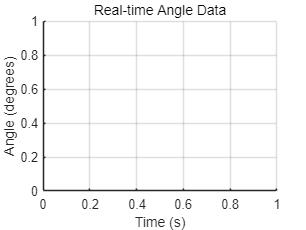

% 그래프 초기화
figure;
hold on;
grid on;
xlabel('Time (s)');
ylabel('Angle (degrees)');
title('Real-time Angle Data');

%legend('Kalman X', 'Kalman Y', 'Gyro Z');



% 데이터 저장을 위한 초기화
rollData = [];
pitchData = [];
yawData = [];
timeStamp = [];


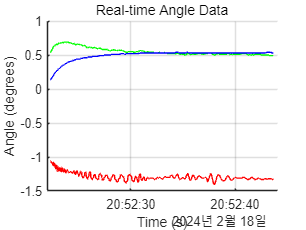

% 데이터 수신 및 그래프 업데이트
try
    % 데이터 수신 및 그래프 업데이트
    while true
        % 아두이노로부터 데이터 읽기
        line = fgetl(s);
        if ~isempty(line)
            % 읽어온 데이터를 쉼표를 기준으로 분리하여 숫자로 변환
            data = str2double(strsplit(line, ','));
            if numel(data) == 3
                % 읽어온 데이터를 해당 변수에 저장
                roll = data(1);
                pitch = data(2);
                yaw = data(3);
                
                % 현재 시간 기록
                currentTime = datetime('now');
                
                % 데이터 저장
                rollData = [rollData, roll];
                pitchData = [pitchData, pitch];
                yawData = [yawData, yaw];
                timeStamp = [timeStamp, currentTime];
                
                % 그래프 업데이트
                plot(timeStamp, rollData, 'r');
                plot(timeStamp, pitchData, 'g');
                plot(timeStamp, yawData, 'b');
                
                % 그래프 업데이트
                drawnow limitrate;
            end
        end
    end
catch ME
    fclose(s);
    rethrow(ME);
end

fclose(s);

delete(s);
clear;
%clear
%clc
%delete(instrfindall); %아두이노와 매트랩의 통신을 끊어 기존에 연결된 포트와의 연결 차단